# Lab 1 - Sampling and Aliasing - R1, R2, R3

## 0. Init

clear;

## 1.

% Continuos time chirp:
% x_c = cos[2*pi*(1/3*k2*t^3 + 1/2*k1*t^2 + F0*t + phi0)]
% Define constants
k1 = 0;
k2 = 1000;
F0 = 0;
phi0 = 0;
%=> x_c = cos[2*pi*1/3*k2*t^3]

% Sampling of x_c -> x
SPS = 8000;
T = [0 2];
t = T(1):1/SPS:T(2);
x = cos(2*pi*(1/3*k2*t.^3 + 1/2*k1*t.^2 + F0*t + phi0));

% play sampled sound
soundsc(x, SPS);

**R1.a)  **

At 8000 SPS it is possible to hear a signal of increasing frequency, which is in accordance with the sampled signal. It, thus, appears that, at this sampling rate, the signal is not distorted. However, if the sampling rate is decreased even just to 6000SPS it is possible to hear a decrease in frequency, which indicates that there was distortion of the sampled signal. 

## 2.

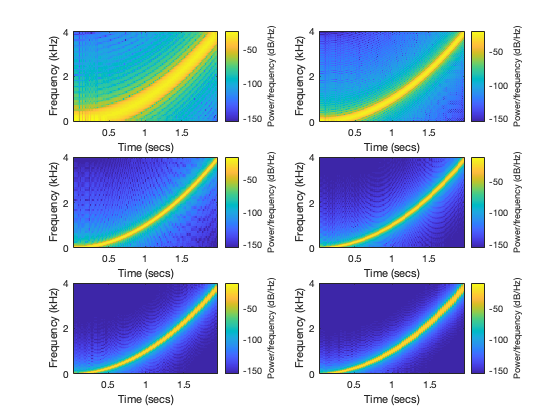

% Set window length
N= 4*[8 20 50 100 150 200];  
% Compute and display spectrogram of x 
figure();
for i = 1:6
    subplot(3,2,i);
    spectrogram(x, hann(N(i)), 3*N(i)/4, 4*N(i), SPS, 'yaxis');
end

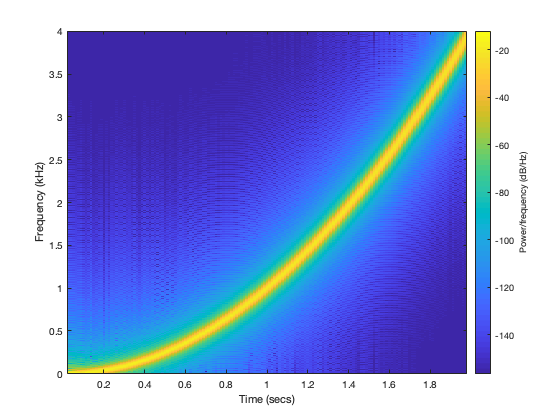

N = 4*100;
figure();
spectrogram(x, hann(N), 3*N/4, 4*N, SPS, 'yaxis');

**R2.a) **From the plots above seem that the best window value is $N=400$. For window sizes below and above $N=400$ the spectrogram is not as sharp. 

**R2.b) **It is in accordance with the monotonically increasing frequency that was heard.

## 3.

% Half the sampling -> y
y = x(1:2:length(x));
SPS_y = SPS/2;

% play sampled sound
soundsc(y, SPS_y);

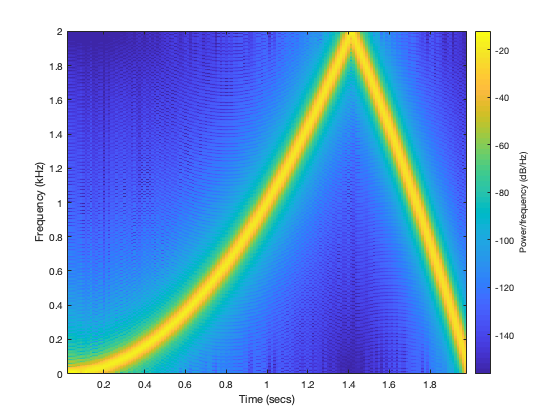

% Adjust window size
N_y = N/2; 
% Compute and display spectrogram of y
figure();
spectrogram(y, hann(N_y), 3*N_y/4, 4*N_y, SPS_y, 'yaxis');

**R3.a) **For each two samples taken in signal x, one is taken in signal the new sampling frequency is half of the sampling frequency of x, i.e., $SPS_y = SPS_x/2 = 8000/2 = 4000 \:SPS$. It, thus, samples @ $f_s=4\mathrm{kHz}$

**R3.b) **It is known that the highest frequency in the selected time window is $f= 4\mathrm{kHz}$. By the Sampling Theorem it follows that for the sampled signal not to distort the original continuous signal, the sampling frequency should be at least twice the highest frequency of the signal, i.e., $f_s\geq 2f=8\mathrm{kHz}$. Notice that the sampling frequency of signal $x(n)$ is $f_s = 8000\mathrm{kHz}$, which, according to the sampling Theorem, is enough not to notice distortion. The sampling frequency of signal $y(n)$, on the other hand, does not satisfy the condition of the Sampling Theorem, therefore, the signal heard is distorted and the spectrogram does not correspond to the spectrogram of the original continuous signal (which is identical to the spectrogram of $x(n)$). Furthermore, it is also important to remark that the beggining of the chirp is heard correclty, which is also visible in the spectrogram of $y(n)$. The interval for which there is not distortion is, as predicted by the Sampling Theorem, until the frequency of the original continuous signal is below half the samppling frequency, i.e., $f = f_s/2=4\mathrm{kHz}/2=2\mathrm{kHz}$.

**R3.c) **

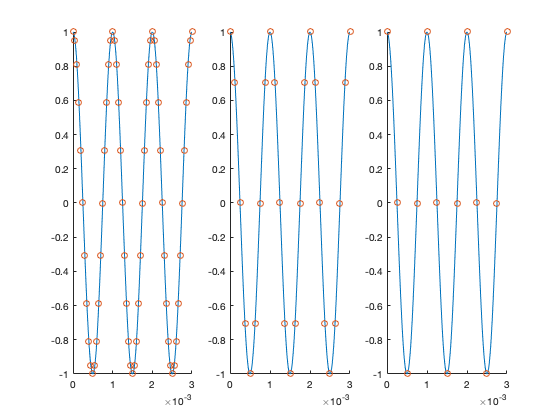

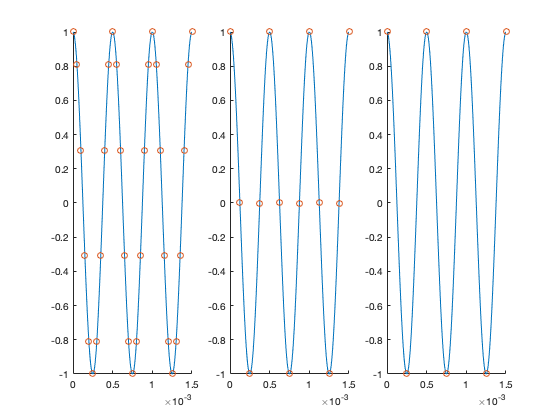

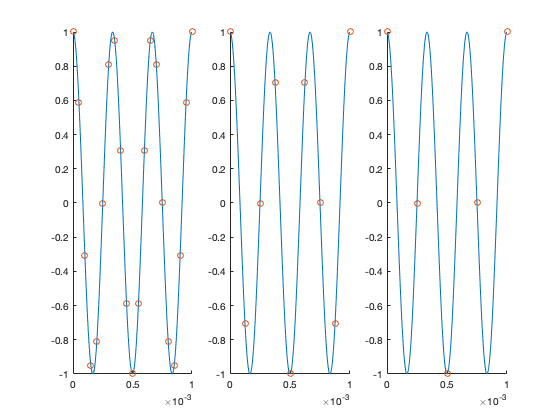

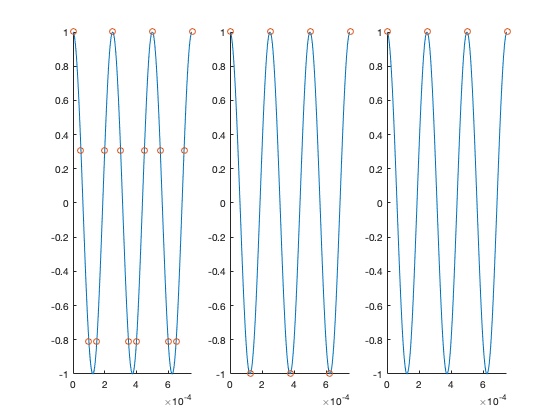

fi = 1e3*[1 2 3 4];
fs = 1e3*[20 8 4];
 for i = 1:4
    t_plot = 0:1/(100*fi(i)):3/fi(i); % consider 3 periods
    z_plot = cos(2*pi*fi(i)*t_plot); 
    figure();
    for j = 1:3
        t_sample = 0:1/fs(j):3/fi(i);
        z_sample = cos(2*pi*fi(i)*t_sample);
        subplot(1,3,j);
        hold on;
        plot(t_plot,z_plot);
        scatter(t_sample,z_sample);
    end  
 end

It is possible to notice that:

- for the frequency $f_1 = 1\mathrm{kHz}$ the sampled signal has the frequency of the original continuous signal for all sampling frequencies $f_s = 20 \mathrm{kHz},\: 8 \mathrm{kHz}, \: 4 \mathrm{kHz}$. This is expected taking into account the Sampling Theorem, which yields $f_s \geq 2\mathrm{kHz}$ for sampling without distortion.

- for the frequency $f_2 = 2\mathrm{kHz}$ the sampled signal has the frequency of the original continuous signal for all sampling frequencies $f_s = 20 \mathrm{kHz},\: 8 \mathrm{kHz}, \: 4 \mathrm{kHz}$. It is also visible that for the sampling frequency $f_s = 4 \mathrm{kHz}$ the sampling signal samples the continupus signal precisely two times per period, which is the absolute minimum for sampling without distortion. This is expected taking into account the Sampling Theorem, which yields $f_s \geq 4\mathrm{kHz}$ for sampling without distortion. Note that the last sampling frequency employed in on the boundary of the condition provided by the Sampling Theorem.

- for the frequency $f_3 = 3\mathrm{kHz}$ the sampled signal has the frequency of the original continuous signal for sampling frequencies $f_s = 20 \mathrm{kHz},\: 8 \mathrm{kHz}$. However, for the sampling frequency $f_s = 4 \mathrm{kHz}$, the continuous signal completes 3 periods in the window considered, whereas the sampling signal completes only one. The frequency of the sampling signal is, thus, $f = 1\mathrm{kHz}$, which does not correspond to the frequency of the original continuous signal, indicating the presense of aliasing. This is expected taking into account the Sampling Theorem, which yields $f_s \geq 6\mathrm{kHz}$ for sampling without distortion. Note that the last sampling frequency employed does not satisfy the condition provided by the Sampling Theorem.

- for the frequency $f_4 = 4\mathrm{kHz}$ the sampled signal has the frequency of the original continuous signal for the sampling frequencies $f_s = 20 \mathrm{kHz},\: 8 \mathrm{kHz}$. Note that $f_4 = 4\mathrm{kHz}$ is the highest frequency of the chirp considered in this problem.  As it was noticed in 3. for sampling frequency $f_s = 4 \mathrm{kHz}$, the continuous signal completes 3 periods in the window considered, whereas the sampling signal remains constant. The frequency of the sampling signal is, thus, zero, which does not correspond to the frequency of the original continuous signal, indicating the presense of aliasing. This is expected taking into account the Sampling Theorem, which yields $f_s \geq 8
\mathrm{kHz}$ for sampling without distortion. It is important to remark, again, that the boundary of the Sampling Theorem's condition is $f_s = 8
 \mathrm{kHz}$, which is the same as the sampling frequency employed in 1., for which the was not distotion of the original signal. 

## Doubts

- Podemos entregar .mlx (MATLAB live script)?

- A frequencia instantanea ve-se fazendo a derivada do sinl, certo? POrtanto, em t= 2 a frequencia de x_c é 4kHz, right?